# 2 Linear regression with one variable

## 2.1 plotting the data

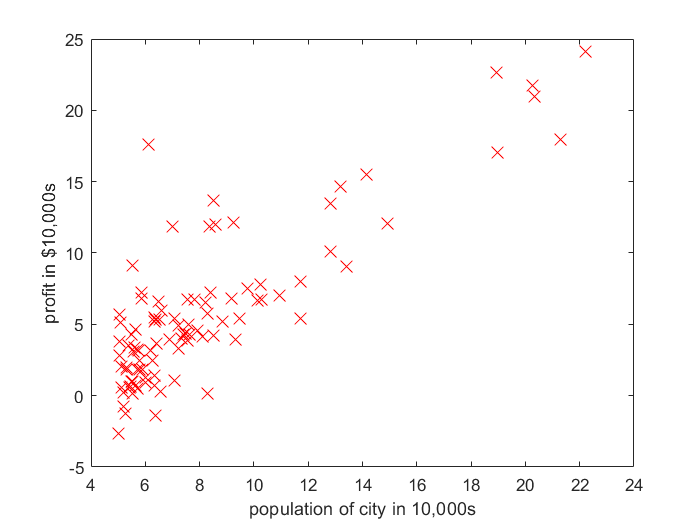

% ex1data1.txt
data = load('./ex1data1.txt');
x = data(:, 1); % 人口
y = data(:, 2); % 利润
m = length(y);
plot(x, y, 'rx', 'markerSize', 10);
ylabel('profit in $10,000s');
xlabel('population of city in 10,000s');

## 2.2 gradient decent

## 2.2.1 update equations


$$j(\theta) = \frac{1}{2m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})^2\\
h_\theta(x) = \theta^Tx = \theta_0 + \theta_1x_1\\
\theta_j := \theta_j - \alpha\frac{1}{m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})x^{(j)}$$


注意 $x^{\left(j\right)}$ 是对应 $\theta_j$ 的特征数据，这里已经统一用向量思维了

## 2.2.2 implementation

增加一个维度给 x，用于对应 $\theta_0$

X = x; % 保留
x = [ones(m, 1), data(:, 1)];
x

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546



theta = zeros(2, 1);
theta

theta =      0
     0


iterations = 1500;
alpha = 0.01;

## 2.2.3 computing the cost $j\left(\theta \right)$

cost_func(x, y, theta, m)

ans = 32.0727

## 2.2.4 gradient descent

we minimize the value of *J*(*θ*) by changing the values of the vector *θ*, not by changing *X *or *y*  

x

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546


y

y =    17.5920
    9.1302
   13.6620
   11.8540
    6.8233
   11.8860
    4.3483
   12.0000
    6.5987
    3.8166


theta = [0.11; 0.14]

theta =     0.1100
    0.1400


theta = zeros(2, 1)

theta =      0
     0


h     = x * theta

h =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


cost  = sum(x .* (h - y), 1);
cost.'

ans = 	1.0e+03 *

   -0.5664
   -6.3369


% 理解以上的形状后，谢自定义函数 gd
train_theta = gd(x, y, 1000, 0.01)

train_theta =    -3.2414
    1.1273



x * train_theta

ans =     3.6465
    2.9899
    6.3616
    4.6533
    3.3643
    6.2086
    5.1867
    6.4286
    4.0705
    2.4566


**注意这里 X 和 x 的使用，**X 是一维，x 加入了一个维度

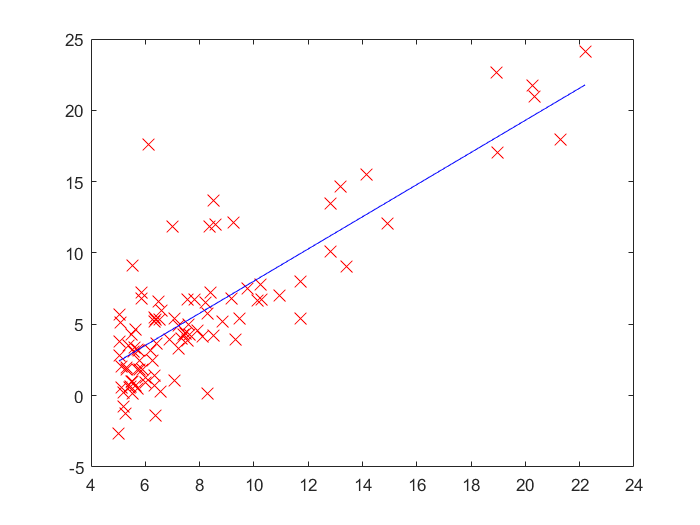

figure;
plot(X, y, 'rx', X, x * train_theta, 'b', 'MarkerSize', 10);

## 函数自定义区

function cost = cost_func(x, y, theta, m)

aa =      1     4
     9    16


    % x .* y 对应元素相乘
    h = x * theta;
    c = (h - y) .^ 2;
    cost = sum(c) / (2 * m);
end




$$j(\theta) = \frac{1}{2m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})^2\\
h_\theta(x) = \theta^Tx = \theta_0 + \theta_1x_1\\
\theta_j := \theta_j - \alpha\frac{1}{m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})x^{(j)}$$


多注意一下矩阵形状。

% 梯度下降，拟合出参数 
function theta = gd(x, y, iterations, alpha)
    theta = zeros(2, 1);
    m = length(y);
    
    for i = 1 : iterations
        h    = x * theta;
        cost = sum((h - y) .* x, 1); % 沿着列加和，这是第一维度
        theta = theta - alpha * cost.' ./ m; % 不转置会发生广播
    end
end